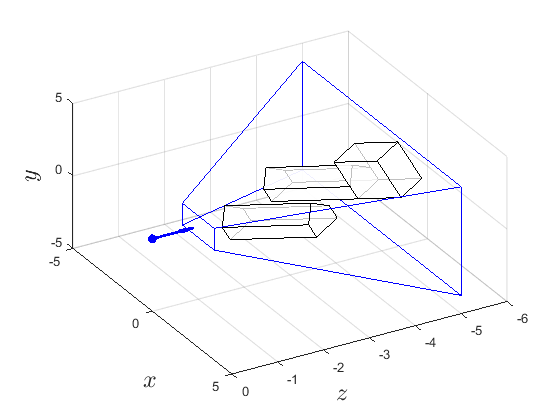

clear

% Load world space coordinates
load('camera_space_coords.mat')

% Define projection parameters
near = 1;
far = 5;
fov = pi/2;
aspect = 4/3;

% Calculate projection matrix
r = near * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ];

% Calculate screen space co-ordinates
Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

% Calculate viewing frustum co-ordinates
r2 = far * tan(fov / 2);
t2 = r2 / aspect;
Vfrustum = [ -r,     r,     r2,  -r2,  -r,     r,     r2,  -r2 ;
             -t,    -t,    -t2,  -t2,   t,     t,     t2,   t2 ;
             -near, -near, -far, -far, -near, -near, -far, -far ;
              1,     1,     1,    1,    1,     1,     1,    1 ];
Ffrustum = [ 4, 3, 2, 1 ;
    1, 2, 6, 5 ;
    2, 3, 7, 6 ;
    3, 4, 8, 7 ;
    1, 5, 8, 4 ;
    5, 6, 7, 8 ];

% Plot camera space with viewing frustum
figure()
h1 = axes;
patch('Vertices', Vcamera([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
patch('Vertices', Vfrustum([1,3,2],:)', 'Faces', Ffrustum, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,0,0,'bo',MarkerFaceColor='b')
quiver3(0,0,0,0,-1,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(60,45)
axis([-5, 5, -6, 0, -5, 5])
grid on

exportgraphics(gcf,'../images/screen_space_example_1.png','Resolution',300) 

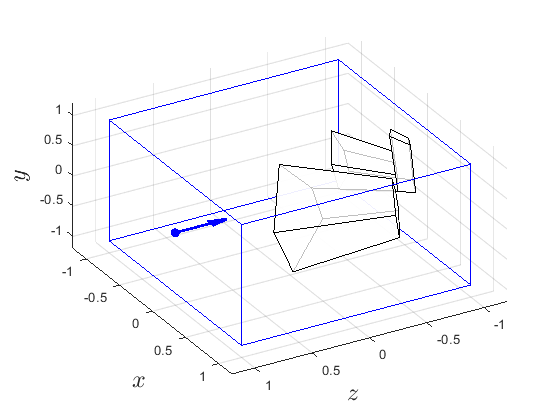

% Calculate transformed viewing frustum
Vcube = P * Vfrustum;
Vcube = Vcube ./ Vcube(4,:);
Fcube = Ffrustum;

% Save camera space co-ordinates
save('screen_space_coords', 'Vscreen', 'F', "Vcube", "Fcube")

% Plot screen space viewed from the side
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
patch('Vertices', Vcube(1:3,:)', 'Faces', Ffrustum, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,1,0,'bo',MarkerFaceColor='b')
quiver3(0,1,0,0,-0.5,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(60,45)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
grid on

exportgraphics(gcf,'../images/screen_space_example_2.png','Resolution',300)

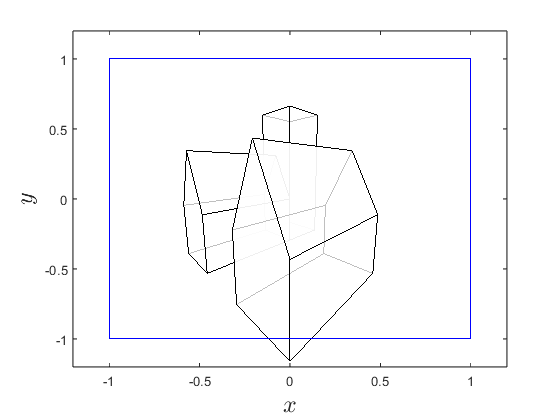

% Plot screen space viewed looking down the z-axis
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
patch('Vertices', Vcube(1:3,:)', 'Faces', Ffrustum, FaceAlpha=0, EdgeColor="blue")
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(0,0)
box on
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])

exportgraphics(gcf,'../images/screen_space_example_3.png','Resolution',300) 